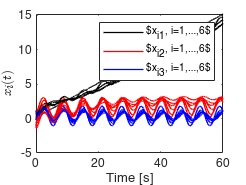

global L d n n_a dist
n = 6; 
n_a =1; n_b = n - n_a;
m = 8;
d = 3;
rng(3);

s = [1 1 2 2 3 3 4 5];
t = [2 4 3 5 4 6 5 6];
G = graph(s,t);
H = incidence(G)'*eye(6);
A12 = [1 0 0; 0 2 1; 0 1 2];
A25 = eye(3); A34 = A25;
A14 = [2 2 0; 2 2 0; 0 0 1];
A36 = A14;
A23 = [2 0 0; 0 0 0; 0 0 1];
A56 = A23;
A45 = [0 0 0; 0 1 0; 0 0 2];

W = blkdiag(A12,A14,A23,A25,A34,A36,A45,A56);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
Z = [zeros(n_a*d,n*d); zeros(n_b*d,n_a*d) eye(d*n_b)];
dist = [0.25;1;1];
x0 = 3*(rand(d*n,1)-0.5);
dhat0 = rand(d*n_b,1);
r0 = [x0;zeros(d*n_b,1);dhat0];
options = odeset('RelTol',1e-7,'AbsTol',1e-6);

% Consensus
[t,r] = ode45(@adaptObsvConsensus,[0:0.01:60],r0,options);
r = r';
x = r(1:d*n,:);
y = r(d*n+1:d*(n+n_b),:);
dhat = r(d*(n+n_b)+1:end,:);

e = zeros(length(t),1);
for i=1:length(t)
    e(i,1) = norm(Z*L*x(:,i));
end

figure
hold on;
for i=1:n
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel('$x_i(t)$','Interpreter','latex');
box on;
legend({'$x_{i1}, i=1,\ldots,6$','$x_{i2}, i=1,\ldots,6$','$x_{i3}, i=1,\ldots,6$'},"NumColumns",1)

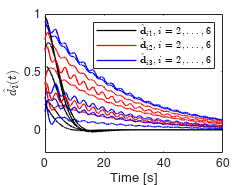


figure
hold on;
for i=1:n-n_a
   plot(t,dhat(3*i-2,:),'-k','LineWidth',1);
   plot(t,dhat(3*i-1,:),'-r','LineWidth',1);
   plot(t,dhat(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel('$\hat{d}_i(t)$','Interpreter','latex');
box on;
legend({'$\hat{\mathbf{d}}_{i1}, i=2,\ldots,6$','$\hat{\mathbf{d}}_{i2}, i=2,\ldots,6$','$\hat{\mathbf{d}}_{i3}, i=2,\ldots,6$'},...
    'Interpreter','latex',"NumColumns",1)

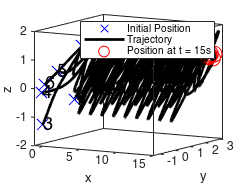


figure
hold on;
for i=1:n
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',2);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
ax = gca;
ax.BoxStyle = 'full';
box on
legend({'Initial Position','Trajectory','Position at t = 15s'}, "NumColumns", 1)
view(30,10)

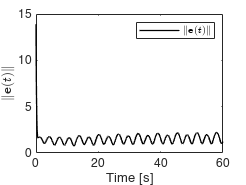


figure
hold on;
plot(t, e, '-k', 'LineWidth', 1);
xlabel 'Time [s]'; ylabel('$\|\mathbf{e}(t)\|$','Interpreter','latex');
box on;
legend({'$\|\mathbf{e}(t)\|$'}, "NumColumns", 1, 'interpreter', 'latex');

function dr = adaptObsvConsensus(t, r)
    global L d n n_a dist
    n_b = n - n_a;
    k = .5; gamma = .1;
    phi = [1 0 0;0 cos(t) sin(t);0 sin(t) cos(t)];
    v_ref = phi*dist;                     % Helical motion along the x-axis
    Z = [zeros(n_a*d,n*d); zeros(n_b*d,n_a*d) eye(d*n_b)];
    x = r(1:d*n,1);
    y = r(d*n+1:d*(n+n_b),1);
    hatd = r(d*(n+n_b)+1:end,1);
    ui = -Z*L*x;
    
    dy = k*(x(d*n_a+1:d*n,1)-y) + ui(d*n_a+1:d*n,1);
    dx = Z*(-L*x + [zeros(d*n_a,1); kron(eye(n_b),phi)*hatd]) + [kron(ones(n_a,1),v_ref); zeros(d*n_b,1)];
    d_hatd = -gamma*kron(eye(n_b),phi)'*(x(d*n_a+1:end,1)-y);
    dr = [dx; dy; d_hatd];
end